Symbolic Expression

close all
clear
clc

syms theta m_rp d h a rho real

I_sc_c_var = comp_intertia(theta, m_rp, d, h, a, rho)

$$I\_sc\_c\_var = \begin{array}{l} \left(\begin{array}{ccc} \frac{\rho \,a^{4}}{6}+\sigma_{3} & 0 & 0\\ 0 & \frac{d^{2}\,m_{\mathrm{rp}}}{6}+\frac{\sigma_{5}}{6}-\sigma_{1}+\frac{\sigma_{4}}{3} & \sigma_{2}\\ 0 & \sigma_{2} & \sigma_{3}+\frac{\sigma_{5}}{3}-\sigma_{1}+\frac{\sigma_{4}}{6} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,a^{2}\,\rho \,{\left(\frac{a}{2}+\frac{d}{2}\right)}^{2}\\ \sigma_{2}=\frac{a^{4}\,\rho \,\cos\left(\theta \right)\,\sin\left(\theta \right)}{6}\\ \sigma_{3}=\frac{m_{\mathrm{rp}}\,\left(d^{2}+h^{2}\right)}{12}\\ \sigma_{4}=a^{4}\,\rho \,{\sin\left(\theta \right)}^{2}\\ \sigma_{5}=a^{4}\,\rho \,{\cos\left(\theta \right)}^{2} \end{array}$$


m_rp = 400;
h = 1.88;
d = 1.14;

a = 1.5;
rho = 2;

I_sc_c_0 = comp_intertia(deg2rad(0), m_rp, d, h, a, rho)

I_sc_c_0 =   162.8208         0         0
         0   72.6459         0
         0         0  148.8267


I_sc_c_45 = comp_intertia(deg2rad(45), m_rp, d, h, a, rho)

I_sc_c_45 =   162.8208         0         0
         0   73.4897    0.8438
         0    0.8438  147.9830



[V, D] = eig(I_sc_c_45);

R = [V(:,3), V(:,1), V(:,2)]

R =     1.0000         0         0
         0   -0.9999    0.0113
         0    0.0113    0.9999


[phi, ~] = rot_to_eul(R);
phi = rad2deg(phi);

New part

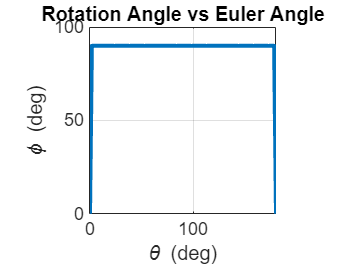

m_rp = 400;
h = 1.88;
d = 1.14;

a = 1.5;
rho = 2;

% Initialize an empty vector to store the Euler angles (phi)
phi_vector = zeros(1, 100);

% Generate 100 points from 0 to pi using linspace
theta_values = linspace(0, pi, 100);

% Loop through the theta values
for i = 1:100
    % Get the current angle (theta) from linspace
    theta = theta_values(i);
    
    % Call the function comp_inertia for the current angle
    I_sc_c_45 = comp_intertia(theta, m_rp, d, h, 1.5, rho);
    
    % Compute eigenvalues and eigenvectors of the inertia matrix
    [V, D] = eig(I_sc_c_45);
    
    % Construct the rotation matrix R
    R = [V(:,3), V(:,1), V(:,2)];
    
    % Compute the Euler angles (phi, a) from the rotation matrix R
    [phi, a] = rot_to_eul(R);
    
    % Convert phi from radians to degrees and store in the vector
    phi_vector(i) = rad2deg(phi);
end

figure;
plot(rad2deg(theta_values), phi_vector, LineWidth=2)
xlabel('\theta (deg)')
ylabel('\phi (deg)')
xlim([0 180])
axis square
grid on
title('Rotation Angle vs Euler Angle')